clc;clear;close all;

# Problem(a)

#### import data

data = importdata('Ming-Li School 1999-9-21 data.xlsx');
Accel = data(:,20);

#### key in parameter

SR = 200; % sampling rate
t = 1/SR*(1:length(Accel))';
F = 0:0.01:5;
sigma = 0.5; %% change sigma
coefs = MCMW_VCF(Accel,F,SR,sigma);

#### plot

figure,surf(t,F,coefs,'LineStyle','none','FaceLighting','phong');
view(0,90),colormap('jet'),xlabel('Time (sec)'),ylabel('Frequency (Hz)');
xlim([0,103]);
ylim([0,5]);
title('Physical Spectrum by MCMW_VCF');
colorbar;

# Problem(b)

#### Hilbert transform

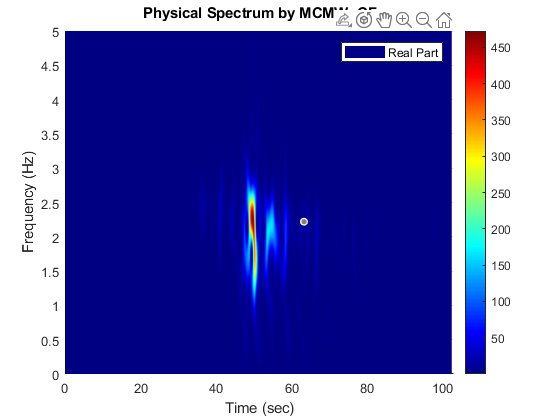

Accel_h = hilbert(Accel);
legend('Real Part');

#### Instantaneous Frequency 

tmp1 = real(Accel_h);
tmp2 = imag(Accel_h);
IF_Accel = (tmp1.*([0;diff(tmp2)])-tmp2.*([0;diff(tmp1)]))./(tmp1.^2)+tmp2.^2;
IF_Accel = IF_Accel*SR/2/pi;
figure;
plot(t,IF_Accel);
xlabel('time (s)');ylabel('Instantaneous Frequency');
title('Instantaneous Frequency by Direct Differentiation');
xlim([0,103]);hold on;

#### data smoothing

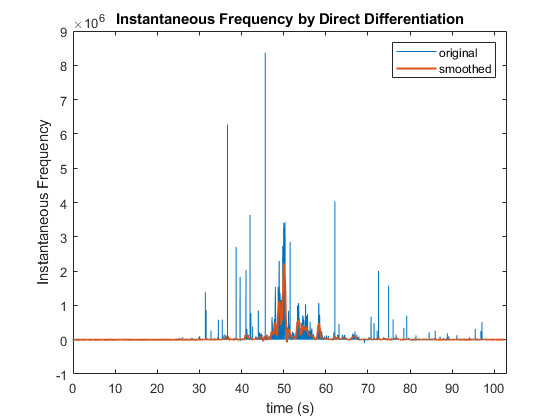

IF_Accel_SM = sgolayfilt(IF_Accel,3,201);
plot(t,IF_Accel_SM,'Linewidth',1.5);
legend('original','smoothed');

# Problem(c)

#### let mean(y) = 0 

y = Accel;
y = y-mean(y);
pt = length(t);
sigma = 0.2;  %% change sigma
winlen = 5;

#### window function

tmp = (-winlen:(1/SR):winlen)';
wpt = length(tmp);
wfun = sqrt(2/(sqrt(2*pi)*sigma))*exp(-tmp.^2/sigma^2);
fps = SR*((1:wpt)'-1)/wpt;
ps = zeros(wpt,pt);

#### short time FT

for I = 1:pt
    idx1 = I-(wpt-1)/2;           
    idx2 = idx1+wpt-1;             
    if (idx1 <= 0)                 
        tmp = [flipud(y(1:(wpt-idx2)));y(1:idx2)];
        tmp = wfun.*tmp;
    elseif (idx1 > (pt-wpt+1))  
        tmp = wpt-(pt-idx1+1);
        tmp = [y(idx1:end);flipud(y((pt-tmp+1):end))];
        tmp = wfun.*tmp; 
    else
        tmp = wfun.*y(idx1:idx2); 
    end
    ps(:,I) = abs(fft(tmp))/wpt*2;
end

#### plot result

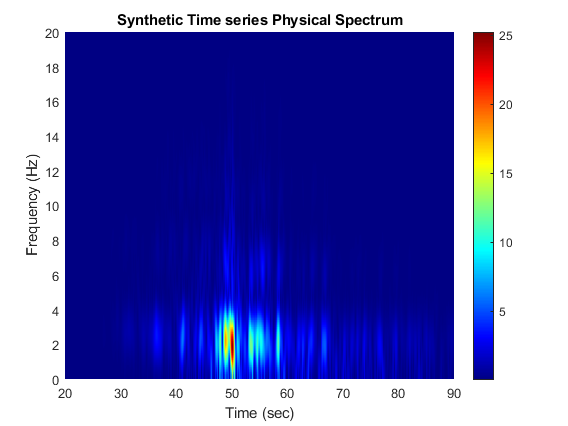

figure,surf(t,fps,ps,'LineStyle','none','FaceLighting','phong');
view(0,90),colormap('jet'),xlabel('Time (sec)'),ylabel('Frequency (Hz)');
xlim([20,90]);ylim([0,20]);title('Synthetic Time series Physical Spectrum');
colorbar;
set(gcf,'Position',[50,50,1024,768]);

# Problem(e)

#### Marginal Spectrum

Confirm the dimension of coefs (501 x 6490). Make sure the row is “time” or “freq”

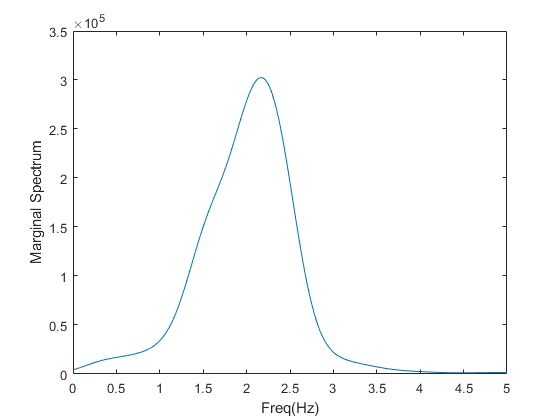

MargSpec = sum(coefs, 2);
figure
plot(F, MargSpec);
xlabel('Freq(Hz)');
ylabel('Marginal Spectrum');

#### coefs function

function coefs = MCMW_VCF(Accel,F,SR,sigma)
if size(Accel,2) == 1
    Accel = Accel';
end
scales = 1;
for s = 1:length(F)
    j = 1;
    for w = (0:length(Accel)-1)*SR/length(Accel)*2*pi
        psi(j) = scales^0.5*((2*pi)^0.5*sigma*exp(-0.5*(w*scales-2*pi*F(s))^2*sigma^2));
        j = j+1;
    end
    coefs(s,:) = 1/2/pi*(ifft(fft(Accel).*conj(psi)));
end
    coefs = abs(coefs);
    coefs = coefs.*coefs;
end